P.22

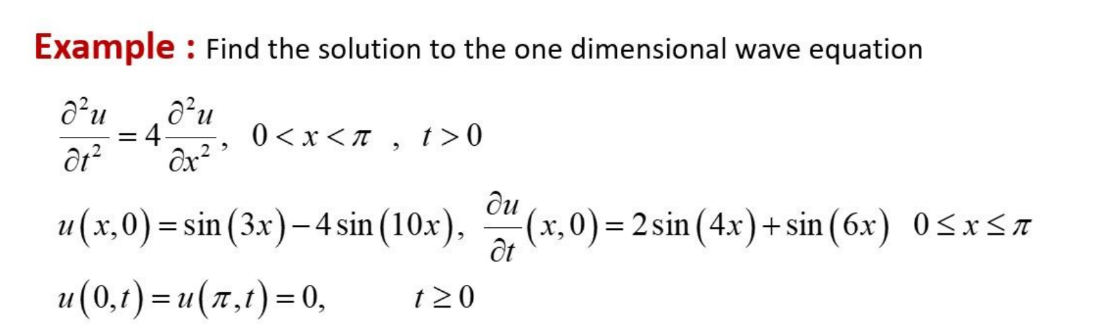

**Separation part**

clear
clc
syms u(x,t) L a f(x) g(x)
assume([L a],"positive")

**wave equation**

WaveEq = a^2*diff(u,x,2) == diff(u,t,2)

$$WaveEq(x, t) = a^{2}\,\frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)=\frac{\partial^{2}}{\partial t^{2}}u\left(x,t\right)$$

BC0 = u(0,t) ==0; BCL = u(L,t) == 0;
t0 = u(x,0) == sin(3*x) - 4*sin(10*x)

$$t0 = u\left(x,0\right)=\sin\left(3\,x\right)-4\,\sin\left(10\,x\right)$$

Dt = diff(u,t);
Dt0 = Dt(x,0) == 2*sin(4*x)+sin(6*x)

$$Dt0 = \left({\left(\frac{\partial }{\partial t}u\left(x,t\right)\right)|}_{t=0}\right)=2\,\sin\left(4\,x\right)+\sin\left(6\,x\right)$$

syms T(t) X(x)
SepVar = subs(WaveEq,u(x,t),X(x)*T(t))

$$SepVar(x, t) = a^{2}\,T\left(t\right)\,\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)=X\left(x\right)\,\frac{\partial^{2}}{\partial t^{2}}T\left(t\right)$$

**Conditions**

BC0 = subs(BC0,u(0,t),X(0))

$$BC0 = X\left(0\right)=0$$

BCL = subs(BCL,u(L,t),X(L))

$$BCL = X\left(L\right)=0$$

T0 = subs(t0,u(x,0),T(0))

$$T0 = T\left(0\right)=\sin\left(3\,x\right)-4\,\sin\left(10\,x\right)$$

DT = diff(T,t);
DT0 = subs(Dt0,Dt(x,0),DT(0))

$$DT0 = \left({\left(\frac{\partial }{\partial t}T\left(t\right)\right)|}_{t=0}\right)=2\,\sin\left(4\,x\right)+\sin\left(6\,x\right)$$

SepVar = SepVar/(X(x)*T(t))

$$SepVar(x, t) = \frac{a^{2}\,\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=\frac{\frac{\partial^{2}}{\partial t^{2}}T\left(t\right)}{T\left(t\right)}$$

**Solving equations**

syms lambda
assume(lambda,"positive")
var = children(SepVar);
eqX = var(1) == - lambda^2

$$eqX = \frac{a^{2}\,\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\lambda^{2}$$

eqT = var(2) == -lambda^2

$$eqT = \frac{\frac{\partial^{2}}{\partial t^{2}}T\left(t\right)}{T\left(t\right)}=-\lambda^{2}$$

X(x,lambda) = dsolve(eqX,BC0);
T(t,lambda) = dsolve(eqT);
constantX = setdiff(symvar(X(x,lambda)),sym(['C',x,lambda,a]));
X(x,lambda) = subs(-X(x,lambda),constantX,sym('C2'));
sln = X(L,lambda) == 0;

**finding lambda**

[lambda,parameter,~] = solve(sln,lambda,"ReturnConditions",true);
n = sym("n",["integer", "positive"]);
lambda = subs(lambda,parameter,n)

$$lambda = \frac{\pi \,a\,n}{L}$$

**Substitution**

syms A B ustruct(x,t,n);
sT(t,n) = subs(T(t,lambda),[lambda,str2sym({'C1','-C2'})],[lambda,{A B}])

$$sT(t, n) = A\,\cos\left(\frac{\pi \,a\,n\,t}{L}\right)+B\,\sin\left(\frac{\pi \,a\,n\,t}{L}\right)$$

sX(x,n) = subs(X(x,lambda),[lambda,sym('C2')],[lambda,sym('1')]);
ustruct(x,t,n) = sX(x,n)*sT(t,n)

$$ustruct(x, t, n) = \sin\left(\frac{\pi \,n\,x}{L}\right)\,\left(A\,\cos\left(\frac{\pi \,a\,n\,t}{L}\right)+B\,\sin\left(\frac{\pi \,a\,n\,t}{L}\right)\right)$$

**Fourier Series part**

syms x t n 
assume(n,"integer")
a = 2; L = pi;
f0 = subs(ustruct(x,0,n),sym("L"),L)

$$f0 = A\,\sin\left(n\,x\right)$$

tf0 = subs(t0,u(x,0),f0)

$$tf0 = A\,\sin\left(n\,x\right)=\sin\left(3\,x\right)-4\,\sin\left(10\,x\right)$$

A_3 = 1

A_3 = 1

A_10 = -4

A_10 = -4

dU = diff(ustruct,t);
g0 = subs(dU(x,0,n),sym(["L","a"]),[L,a])

$$g0 = 2\,B\,n\,\sin\left(n\,x\right)$$

tg0 = subs(Dt0,Dt(x,0),g0)

$$tg0 = 2\,B\,n\,\sin\left(n\,x\right)=2\,\sin\left(4\,x\right)+\sin\left(6\,x\right)$$

B_4 = 1/4

B_4 = 0.2500

B_6 = 1/12

B_6 = 0.0833

u(x,t) = A_3*cos(6*t)*sin(3*x)+A_10*cos(20*t)*sin(10*x)+B_4*sin(8*t)*sin(4*x)+B_6*sin(12*t)*sin(6*x)

$$u(x, t) = \cos\left(6\,t\right)\,\sin\left(3\,x\right)-4\,\cos\left(20\,t\right)\,\sin\left(10\,x\right)+\frac{\sin\left(8\,t\right)\,\sin\left(4\,x\right)}{4}+\frac{\sin\left(12\,t\right)\,\sin\left(6\,x\right)}{12}$$

**3D** **PLOT**

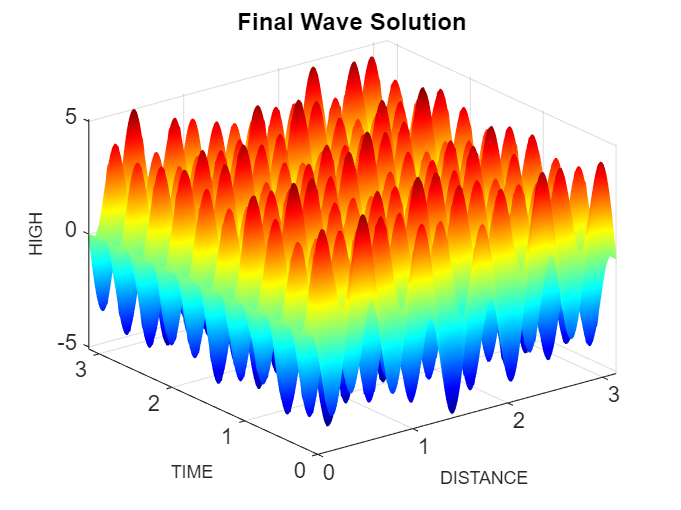

clf
figure
colormap jet
fsurf(u,[0 L 0 L],"EdgeColor","interp")
title("Final Wave Solution")
xlabel('DISTANCE','FontSize',8)
ylabel('TIME','FontSize',8)
zlabel('HIGH','FontSize',8)

**Wave profile at different times**

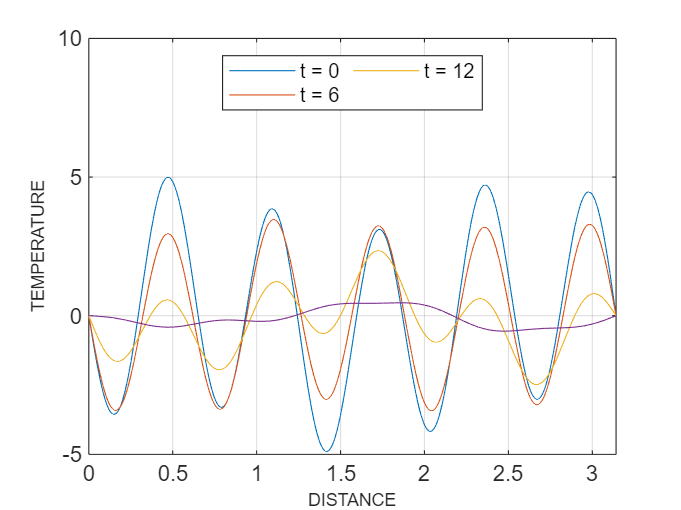

clf
tm = [0 6 12 15];
for i = 1:length(tm)
    sn = matlabFunction(u(x, tm(i)));
    fplot(sn, [0 L])
    grid on, hold on
end
xlabel('DISTANCE', 'Fontsize', 8);
ylabel('TEMPERATURE', 'Fontsize', 8);
ylim([-5 10])
legend('t = 0','t = 6','t = 12','Location','north','NumColumns',2)

**Wave profile at various distances**

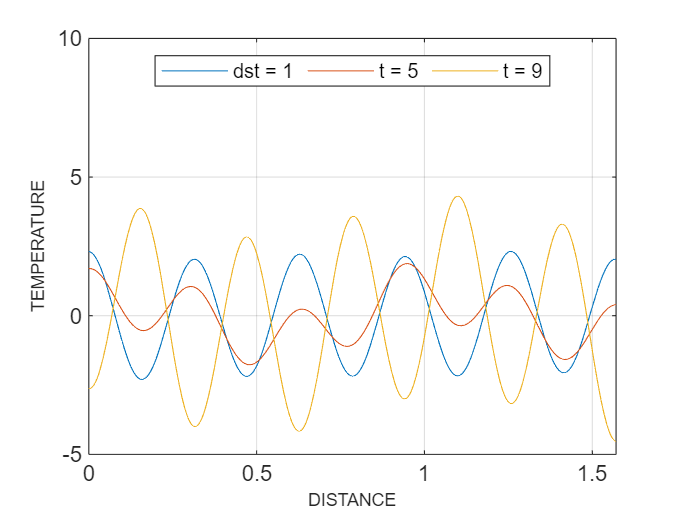

clf
dst = [1 5 9];
for i = 1:length(dst)
    sn = matlabFunction(u(dst(i),t));
    fplot(sn, [0 pi/2])
    grid on, hold on
end
xlabel('DISTANCE', 'Fontsize', 8);
ylabel('TEMPERATURE', 'Fontsize', 8);
ylim([-5 10])
legend('dst = 1','t = 5','t = 9','Location','north','NumColumns',3)